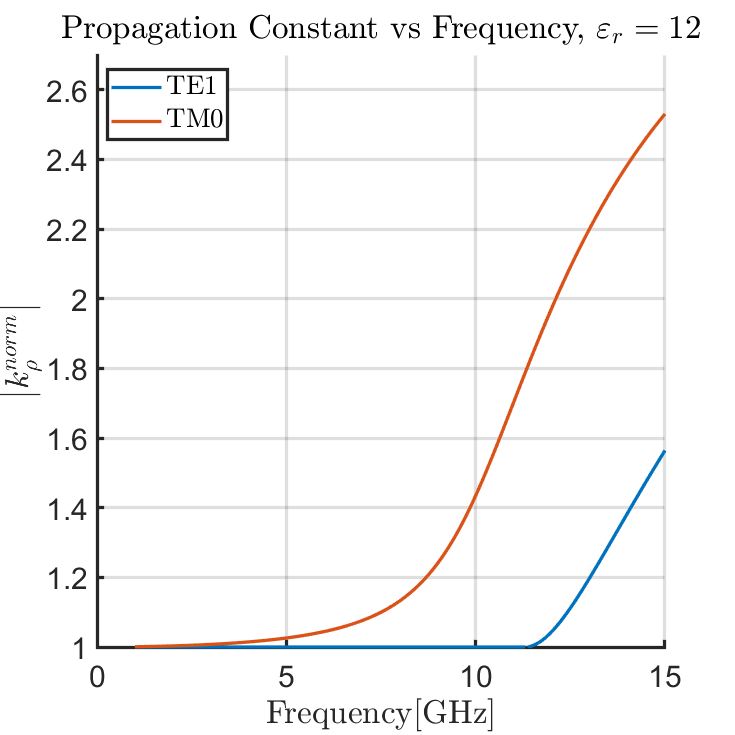


clear all
h = 2e-3;
z = h+eps ;
er = 12 ;
freq = 20.*1e9 ;
freqn = linspace(1e9,15e9,1001);
lambdan=3e8./freqn ;
lambda = 3e8./freq ;
k0 = 2*pi./lambda ;
ky = 0 ;
zeta0 = 120*pi ;
no_ofpt = 1001 ;

lst= k0.*sqrt(er) ;
krho = linspace(eps,lst,no_ofpt) ;
krho_norm = linspace(1,sqrt(er),no_ofpt) ;

% figure
% plot(krho./k0,abs(D))
% figure
% plot(krho./k0,abs(Dn))
% plot(freqn,abs(krholoop))
for ii = length(freqn):-1:1
    k0 = 2.*pi.* freqn(ii)./3e8 ;
    krho = krho_norm .* k0 ;
    [krhonte(ii),krho_newte(ii)] = IterativeMethod(h,1,er,freqn(ii),'GroundSlab','TE',krho) ;
    [krhontm(ii),krho_newtm(ii)] = IterativeMethod(h,1,er,freqn(ii),'GroundSlab','TM',krho) ;
end
figure
hold on
TE = plot(freqn./1e9,abs(krhonte),'DisplayName','TE1') ;
TM = plot(freqn./1e9,abs(krhontm),'DisplayName','TM0') ;
ylim([1 2.7]) 
title(sprintf('Propagation Constant vs Frequency, $\\varepsilon_r=%.f$',er),'Interpreter','latex') ;
xlabel('Frequency[GHz]','Interpreter','latex');
ylabel('$\left|k_\rho ^{norm}\right|$','Interpreter','latex') ;
legend('Interpreter','latex','Location','best')
grid on;
ax = gca;
ax.FontSize = 18 ;

ax.LineWidth = 2 ;
TE.LineWidth = 2;
TM.LineWidth = 2 ;

## Question 2: 

Write a Matlab routine to calculate the field contribution, in cylindrical coordinates,  associated to the TM0 surface wave excited by a half-wavelength dipole (l=15 mm, w=0.5 mm) on top of a grounded slab. Provide the following plots (h=2 mm, εr=10, f=10 GHz):

• Real and imaginary part variation of the electric field as a function of the radial  distance. Finished(Need to create better plots)

• Amplitude variation of the electric field components as a function of z. 

• Amplitude variation of the electric field as a function of φ. Finished(Need to create better plots)

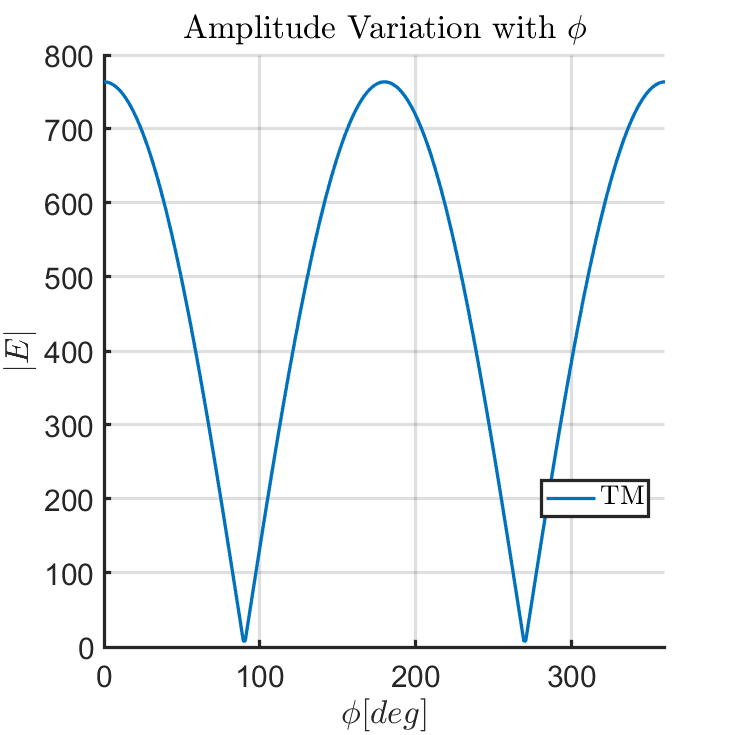

clear 
l = 3e-3 ;
w = 1e-3 ;
h = 2e-3 ;
er = 12; 
f= 10e9 ;
k0 = 2.*pi.* f./3e8 ;
no_ofpt = 1001 ;
phi = linspace(eps,2*pi,303) ;
lambdas = 3e8./(f.*sqrt(er)) ;
rho = linspace(eps,15 .*lambdas,303) ;% linspace(eps,1,200) ;
[RHO,PHI] = meshgrid(rho,phi) ;
z = linspace(eps,h+23e-3,303) ;

lst= k0.*sqrt(er) ;
krho = linspace(eps,lst,no_ofpt) ;
% Erhotm=zeros(size(RHO))
for ii = 1:length(z)
    [~,kswTM] = IterativeMethod(h,1,er,f,'GroundSlab','TM',krho) ;
    [VrTM,IrTM] = Residue_GroundSlab(k0,er,h,kswTM,z(ii),f,'TM') ;
    [Erhotm(:,:,ii),~,Eztm(:,:,ii)] = SwFields(k0,kswTM,er,VrTM,IrTM,RHO,PHI,l,w) ;
    EtotTM(:,:,ii) = sqrt( abs(Erhotm(:,:,ii)).^2 + abs(Eztm(:,:,ii)).^2 ) ;

    [~,kswTE] = IterativeMethod(h,1,er,f,'GroundSlab','TE',krho) ;
    [VrTE,IrTE] = Residue_GroundSlab(k0,er,h,kswTE,z(ii),f,'TE') ;
    [Erhote(:,:,ii),~,Ezte(:,:,ii)] = SwFields(k0,kswTE,er,VrTE,IrTE,RHO,PHI,l,w) ;
    EtotTE(:,:,ii) = sqrt( abs(Erhote(:,:,ii)).^2  + abs(Ezte(:,:,ii)).^2 ) ;
end
% [~,~,ResTM,~] = residue_stratified(k0, kswTE, kswTM, z, 'GroundSlab',h,er)

figure 
hold on
ETM = plot(rad2deg(phi),(EtotTM(:,length(rho),13)),'DisplayName','TM') ;
% plot(rad2deg(phi),(EtotTM(:,:,13)),'DisplayName','TE') ;
hold off
legend('Location','best','Interpreter','latex')
xlabel('$\phi[deg]$', 'Interpreter','latex');
ylabel('$\left|E\right|$', 'Interpreter','latex');
title('Amplitude Variation with $\phi$','Interpreter','latex')
xlim([0 360]) ;
grid on ;
ax = gca ;
ax.FontSize = 18 ;

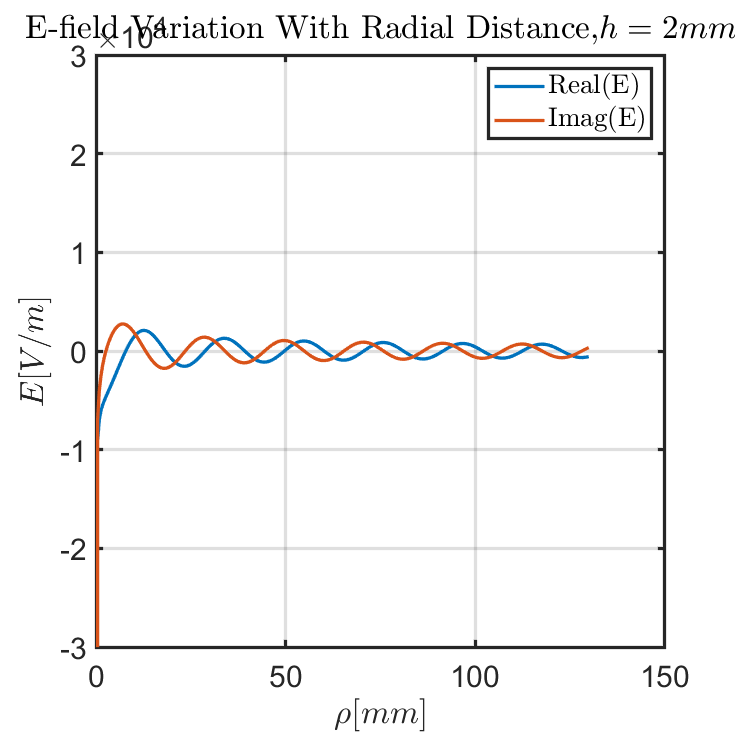

ax.LineWidth = 2 ;
ETM.LineWidth = 2 ;

figure
Re = plot((rho)./1e-3,(real(Erhotm(1,:,13))),'DisplayName','Real(E)') ;
hold on
Im = plot((rho)./1e-3,(imag(Erhotm(1,:,13))),'DisplayName','Imag(E)') ;
legend('Interpreter','latex')
title(sprintf('E-field Variation With Radial Distance,$h= %.f mm$',h./1e-3),'Interpreter','latex') ;
xlabel('$\rho[mm]$','Interpreter','latex') ;
ylabel('$E[V/m]$','Interpreter','latex') ;
grid on ;
ylim([-3e4 3e4])
ax = gca ;
ax.FontSize = 18 ;

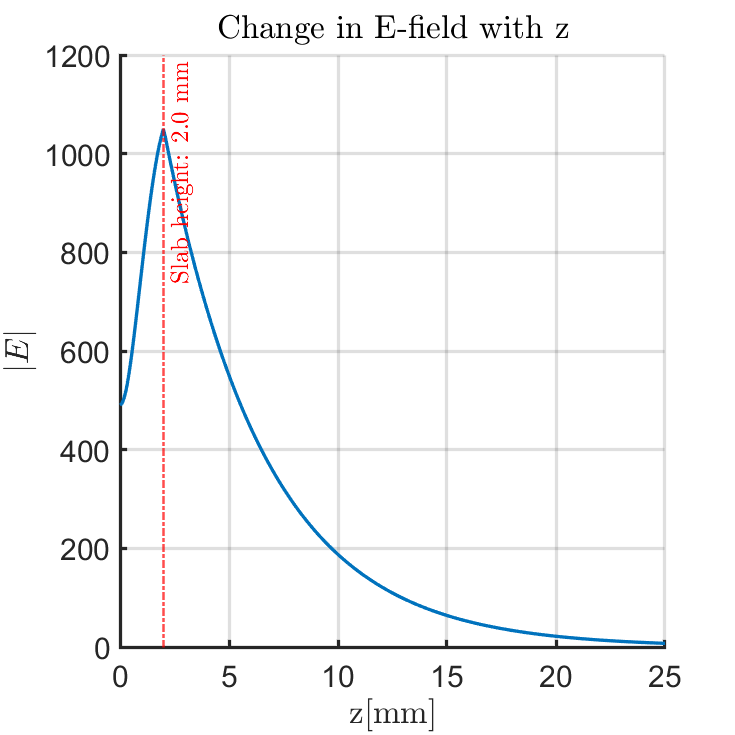

ax.LineWidth = 2 ;
Re.LineWidth = 2 ;
Im.LineWidth = 2 ;


figure
hold on 
p = plot(z./1e-3,squeeze(EtotTM(1,length(rho),:)),'DisplayName','z') ;
Xl = xline(h./1e-3,'r-.',sprintf('Slab height: %.1f mm',h./1e-3),'Interpreter','latex') ;
hold off
grid on;
ylabel('$\left|E\right|$','Interpreter','latex')
xlabel('z[mm]','Interpreter','latex')
title('Change in E-field with z','Interpreter','latex')
ax= gca ;
ax.FontSize = 18 ;
ax.LineWidth = 2 ;
Xl.LineWidth = 1.5 ;
Xl.FontSize = 15 ;

p.LineWidth = 2 ;

## Question 3: 

Write a Matlab routine to calculate the power radiated into the TM0 surface wave of a dipole antenna printed on top of a grounded slab. Provide the following plots (ℎ = 2 mm, 𝜀𝑟 = 10, 𝑓 = 1 − 15 GHz):

 -> The far field power and surface wave power radiated by an elementary dipole (𝐽 = 1) normalized to the power radiated by the same dipole in free space.

-> The TM0 surface wave efficiency for the elementary dipole and for a dipole with 𝑙 = 5.3 mm and 𝑤 = 0.5 mm (assume a PWS distribution). 

-> The TM0 surface efficiency for a uniform current distribution in both 𝑥 and 𝑦 directions with a dimension of 𝑙 = 𝑤 = 25 mm

## Far-field from Elementary, Uniform And PWS Current Distribution

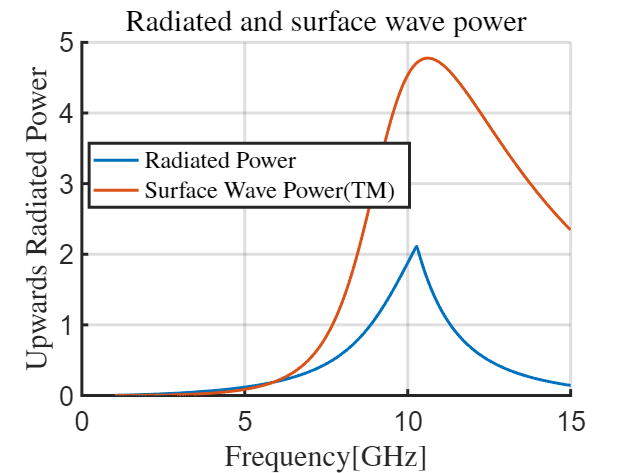



clear


numth=101;
numph= 303;
l = 25e-3 ;%15e-3 ;
w = 25e-3 ;%0.5e-3 ;
h = 2.2e-3 ;
er = 12; 
f= linspace(1,15,303)*1e9;%1.3748e+10 ;
k0 = 2.*pi.* f./3e8 ;
no_ofpt = 1001 ;
phi1 = linspace(eps,2*pi,303) ;
lambdas = 3e8./(f.*sqrt(er)) ;
theta = linspace(eps,pi/2,numth);
phi = linspace(eps,2*pi,numph);
[TH,PHI] = meshgrid(theta,phi1);



lst= k0.*sqrt(er) ;
% Erhotm=zeros(size(RHO))
for ii = 1:length(f)
    krho = linspace(eps,lst(ii),no_ofpt) ;
    rho = linspace(eps, 15 .*lambdas(ii),101) ;% linspace(eps,1,200) ;
    [RHO,PHI] = meshgrid(rho,phi) ;

    % TM Power Radiated by Elementart Source
    [~,kswTM] = IterativeMethod(h,1,er,f(ii),'GroundSlab','TM',krho) ;
    [P_TMdelt(ii)]= PswTMelem(f(ii),er,h,kswTM,'TM') ;
  
    IphiPWS  = PhiInt_PWS(er,k0(ii),kswTM,3e-3,1e-3) ;
    IphiUniform = PhiInt_Uniform(kswTM,25e-3,25e-3) ;
    
    % Surface Wave Radiated Power(PWS)
    PTMPWS(ii) = P_TMdelt(ii) .* IphiPWS ./ pi ;
    PTMPWS(isnan(PTMPWS)) = 0 ;
    
    % Surface Wave Radiated Power(Uniform)
    PTMUniform(ii) = P_TMdelt(ii) .* IphiUniform ./ pi ;
    PTMUniform(isnan(PTMUniform)) = 0 ;

    [kx,ky,kz] = PropVectors(k0(ii),TH,PHI) ;

    % calculate voltages and currents
    ej_SGF = EJ_SGF(1, k0(ii), kx, ky);
    Gxx = ej_SGF(:,:,1,1);
    Gyx = ej_SGF(:,:,2,1);
    Gzx = ej_SGF(:,:,3,1);

    dth = theta(2) - theta(1);
    dph = phi(2) - phi(1);

    % calculate far field of the free space dipole
    [Eth, Eph] = farfield(TH, PHI, kz, Gxx, Gyx, Gzx, 1,0,1,0,k0(ii));
    E_tot_element = sqrt(abs(Eth).^2 + abs(Eph).^2);
    [~, Pradiated_element(ii)] = Direc(E_tot_element, TH, dth, dph, 1); 

    % calculate far field of PWS in the free space
    JxPWS = FTCurrent(k0(ii),kx,ky,3e-3,1e-3) ;
    [Eth, Eph] = farfield(TH, PHI, kz, Gxx, Gyx, Gzx, JxPWS,0,1,0,k0(ii)) ;
    Etot = sqrt(abs(Eth).^2 + abs(Eph).^2) ;
    [~, pradFS_pws(ii)] = Direc(Etot, TH, dth, dph, 1);

    % Radiated power of the grounded slab
    R_FF = 1;
    zeta0 = 120*pi ;

    % Prad to free space from elementary current
    lambda = 3e8 / f(ii);
    k1 = k0(ii).*sqrt(er) ;
    keq = (k0(ii)+k1)./2 ;

    KX   = k0(ii) * sin(TH) .* cos(PHI);
    KY   = k0(ii) * sin(TH) .* sin(PHI);
    KZ   = k0(ii) * cos(TH);
    KRHO = sqrt(KX.^2 + KY.^2);
    Z    = R_FF * cos(TH);

    [vtm, vte, itm, ite, kzs ,kz0] = txline_GroundSlab(k0(ii),zeta0,er,Z,h,KRHO,f(ii)) ;
    ej_sgf = SpectralGFej(k0(ii),k1,1,KX,KY,vtm,vte,itm,ite,zeta0,KRHO,Z,h) ;
    Gxx = ej_sgf(:,:,1,1) ;
    Gyx = ej_sgf(:,:,2,1) ;
    Gzx = ej_sgf(:,:,3,1) ;

    [Eth, Eph] = farfield(TH, PHI, KZ, Gxx, Gyx, Gzx, 1,Z,1,h,k0(ii)) ;
    Etot = sqrt(abs(Eth).^2 + abs(Eph).^2) ;
    [~, prad(ii)] = Direc(Etot, TH, dth, dph, R_FF);

    % Power Radiated from Uniform current
    JxUniform = Current_Uniform(TH,PHI,k0(ii),25e-3,25e-3) ;
    [Eth, Eph] = farfield(TH, PHI, KZ, Gxx, Gyx, Gzx, JxUniform,Z,1,h,k0(ii)) ;
    Etot = sqrt(abs(Eth).^2 + abs(Eph).^2) ;
    [~, prad_uniform(ii)] = Direc(Etot, TH, dth, dph, R_FF);

    % Power Radiated from PWS current
    JxPWS = FTCurrent(keq,KX,KY,3e-3,1e-3) ;
    [Eth, Eph] = farfield(TH, PHI, KZ, Gxx, Gyx, Gzx, JxPWS,Z,1,h,k0(ii)) ;
    Etot = sqrt(abs(Eth).^2 + abs(Eph).^2) ;
    [~, prad_pws(ii)] = Direc(Etot, TH, dth, dph, R_FF);


end

figure;
hold on 
PradP = plot(f./1e9,abs(prad_pws)./abs(pradFS_pws) .*0.5 ,'DisplayName','Radiated Power');
PswP = plot(f./1e9,abs(PTMPWS)./abs(pradFS_pws) .*0.5 ,'DisplayName','Surface Wave Power(TM)');
title('Radiated and surface wave power','Interpreter','latex') ;
xlabel('Frequency[GHz]','Interpreter','latex');
ylabel('Upwards Radiated Power','Interpreter','latex') ;
legend('Location','best','Interpreter','latex');
grid on
ax = gca ;
ax.LineWidth = 2 ;
ax.FontSize = 18 ;
PradP.LineWidth = 2 ;
PswP.LineWidth = 2 ;

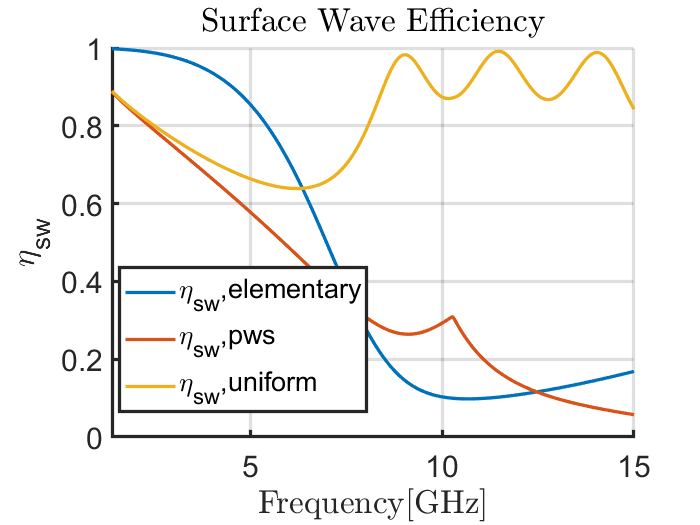


P_TMdelt(isnan(P_TMdelt)) = 0 ;
eta_sw_elem = Pradiated_element./(P_TMdelt+Pradiated_element) ;
eta_sw_pws = prad_pws./(PTMPWS+prad_pws);
eta_sw_uniform = prad_uniform./(PTMUniform+prad_uniform) ;

figure;
hold on
eta_elem = plot(f./1e9,eta_sw_elem,'DisplayName','\eta_{sw},elementary') ;
eta_pws = plot(f./1e9,eta_sw_pws,'DisplayName','\eta_{sw},pws') ;
eta_uni = plot(f./1e9,eta_sw_uniform,'DisplayName','\eta_{sw},uniform') ;
xlim([1.4 15])
xlabel('Frequency[GHz]','Interpreter','latex');
ylabel('\eta_{sw}') ;
legend('Location','best')
title('Surface Wave Efficiency','Interpreter','latex')
grid on;
ax = gca ;
ax.LineWidth = 2 ;
ax.FontSize = 18 ;
eta_elem.LineWidth = 2 ;
eta_uni.LineWidth = 2 ;
eta_pws.LineWidth = 2 ;